# Mobile robot open loop simulation

clear all
close all

## Initialize Shared Simulation Parameters

For the simulation, the initial state of the robot must be defined including position, velocity, and acceleration of each joint.

% Define initial state
q0 = [4;0;pi/4]; 

% Contant linear velocity
v_=0.1; %[m/s]
% Contant angular velocity
%w_=pi/50; %[rad/s]

### Simulate the Model

**Run** the model by calling `sim`.

simout = sim("controlangulo_of_TurtlebotClosedLoop_template.slx");

## **Visualize The Motion of Robot**

After simulating the model, visualize the robot driving the obstacle-free path in the map.

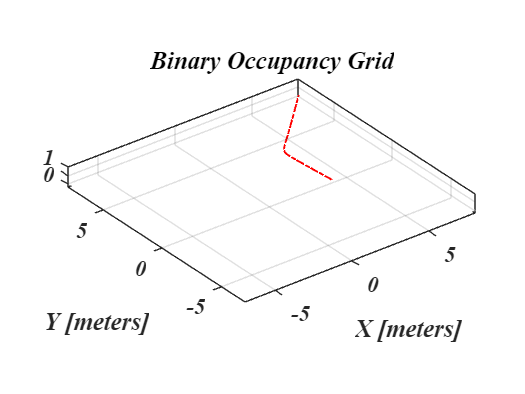

q = simout.yout{1}.Values.Data;
phiIdx = 3;

% Translation
xyz = q;
xyz(:, phiIdx) = 0; % set z = 0

% Rotation in XYZ euler angles
phi = q(:,phiIdx);
thetaEuler = zeros(size(q, 1), 3 * size(phi, 2));
thetaEuler(:, end) = phi;

% Plot the robot poses at every 10th step.
% figure(1)
% cla
map = binaryOccupancyMap(15,15);
move(map,[-7.5,-7.5]);
for i = 1:10:size(xyz, 1) 
    show(map)
    hold on;
    grid on;

    % Plot the trajectory of the robot
    plot(q(:, 1), q(:, 2), '-.r')
    
    % Plot the robot pose as it traverses the path.
    quat = eul2quat(thetaEuler(i, :), 'xyz');
    plotTransforms(xyz(i,:), quat, 'MeshFilePath',...
        'groundvehicle.stl');
    light;
    drawnow;
    hold off;
end